# Testing generated graphs

format shortG
addpath("functions")
% data Options
do = [0,0];

why is the embedding not calculated as desired?

% [nodes,edges,n,emb,M,P,Cos,Sin] = build("01");
% col1 = [0, 1, 0];
% col2 = [1, 0, 0];
% 
% spy(Cos,'x');
% spy(M)
% gplot(Cos,emb)
% plot(emb(:,1),emb(:,2),".")
% plotColorgradient(2,col1,col2,emb,true,true)

Consider making the directed graph an undirected on from Tristans data. For this we need to check first whether the two edge angles are opposite to each other...

If they are **not, **then we cannot do this! 

If they **are,** then we can savely generate an undirected graph from the data

**EDIT**

The in and out angles should not be the same, as we precisely for this occasion to want to minimize the angular error. The shift of angles over the graph (north direction) should affect the two respective directed edges between two nodes in such way, that the angles do not match...

Check again on this statement!

For visualization: We add up the north shifts of each node to the angles of the outgoing edges of the respective nodes, so we get it drawing accordingly in the graphs! With sufficient north shifts we should be able to see, that the edges do not hit target (the ingoing nodes), as they do in a graph without north shifts...

For this we need to draw not a gplot() graph, as the lines are not drawn according to the angles there:

**EDIT 20210202**

The embeddings either do not get drawn/calculated, as the given graphs and their respective matrices are singular, or the nodes do get embedded in the same spatial position in the graph (see plotCompare("03")) and are not distiguishable, while fulfilling the desired goal of minimizing differences.

**EDIT 20210207**

We will now do some changes to the **build()** function, in particular we do exclude those rows from **M **and **P**, that do have **a_ij = 0**, e.g. those rows that are not interconnected.

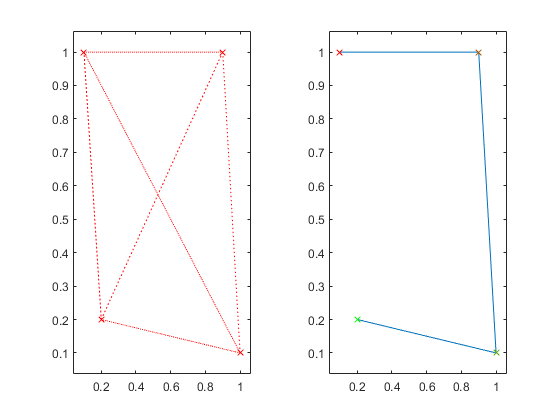

plotTiled("01");

plotTiled("01b");

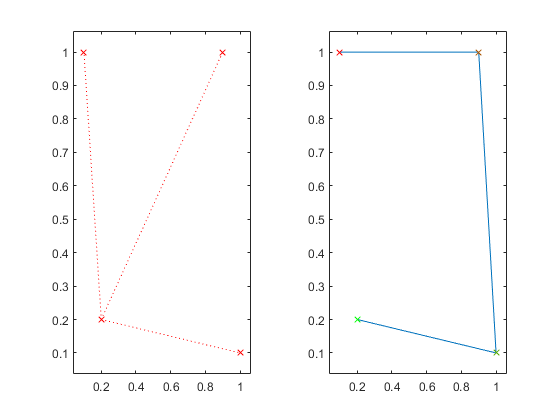

plotTiled("02");

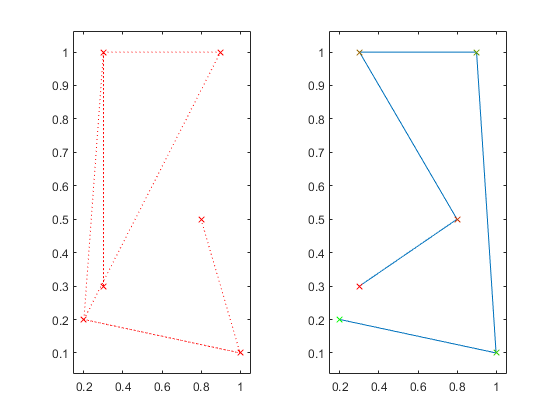

plotTiled("03");

Here we try to draw the nodes and the lines from the nodes to the points, but not from point to point, but from the node at an angle with the fitting length, e.g. the length between the two nodes.

If we choose to reread the data (attribute in **plotCompare()**), we get a warning when the matrix in the embedding calculation is singular. For an example call **build("01")**.

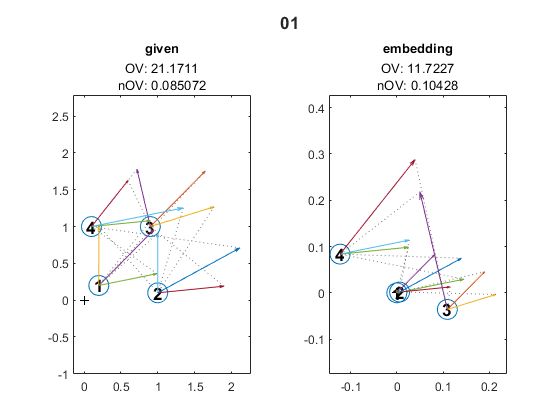

plotCompare("01",do);

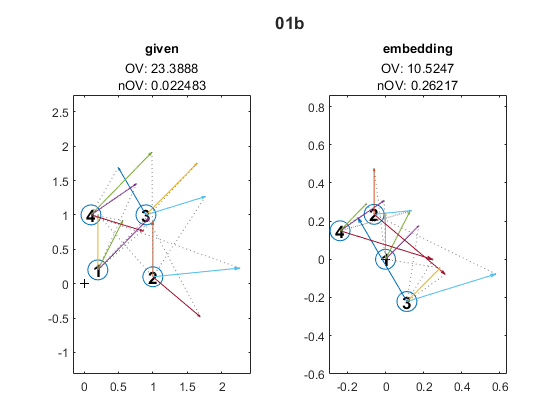

plotCompare("01b",do);

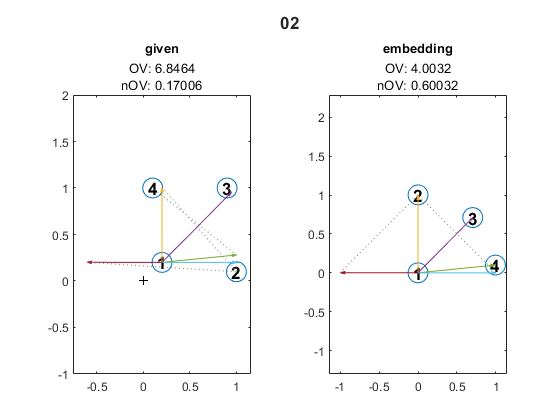

plotCompare("02",do);

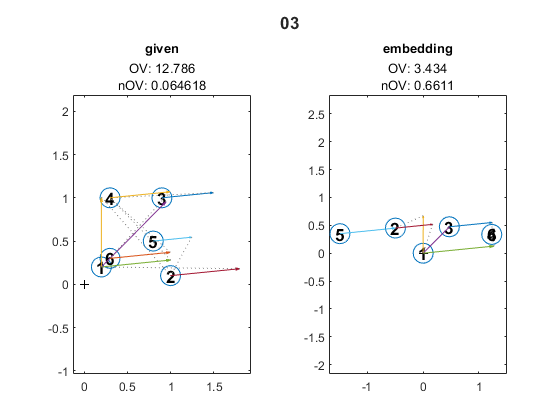

plotCompare("03",do);

This last plot does show what is to be done:

The embedding should result in an arc, as the edges do not form any form of cycles but rather a single path from node **1 **to node **6**. The arc embedding would minimize the differences between the angles.

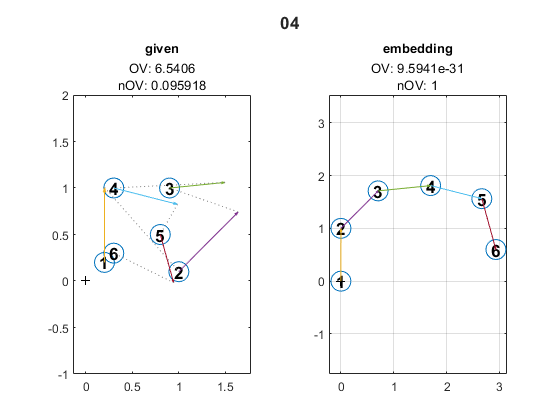

plotCompare("04",do);

While the embedding of **04b** does form a line, node **3** is farthest to the right, while nodes **4** to **6 **seem to inhabit the same positions as at least one other node...

Why does the emedding not form a straight line?

EDIT 20210206

This was updated, so that they dont lay on the same spot anymore, not intentionally, but as a byproduct of changes in **build.m **or others

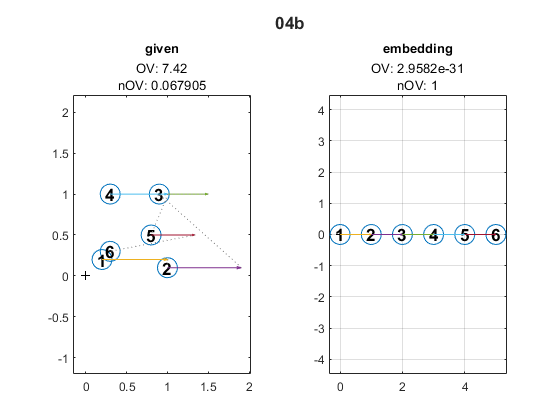

plotCompare("04b",do);
% plotCompareOptions("04b",1,1,0,0,1,0,1,1,do);

With **04c** we generated an initial nearly perfect embedding with a very low OV. Clearly the supposed to be best embedding got a much higher rating on the OV and does not fulfill the desired conditions.

Investigation on this matter will be continued.

What can be stated though, is by comparing **04 **and **04c** we see that the initial embedding of the graph does not matter for the calculated one. What does matter, if we look at **04b** is that the angles do change the embedding.


merging...
Elapsed time is 0.159945 seconds.

building M...
Elapsed time is 0.001561 seconds.

building P...
Elapsed time is 0.000602 seconds.


times =       0.15992    0.0015444     0.000586


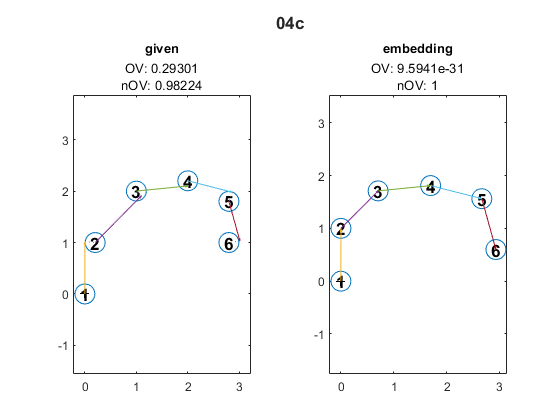

plotCompare("04c",do);

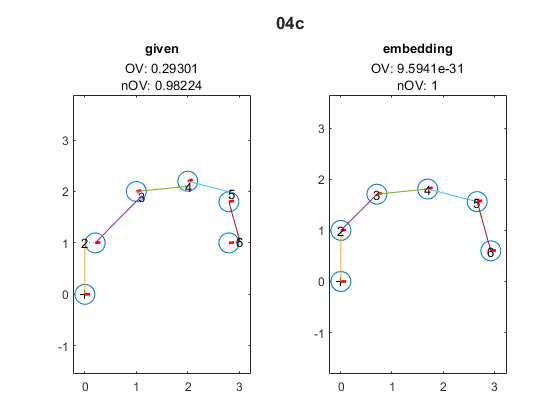


merging...
Elapsed time is 0.014521 seconds.

building M...
Elapsed time is 0.000381 seconds.

building P...
Elapsed time is 0.000200 seconds.


times =      0.014501    0.0003676    0.0001842


plotCompareOptions("04c",1,1,0,1,1,0,1,1,do);

In this case the second node should just move slightly to the top right to fit the direction and probably best keep a distance of 1!

Do it...

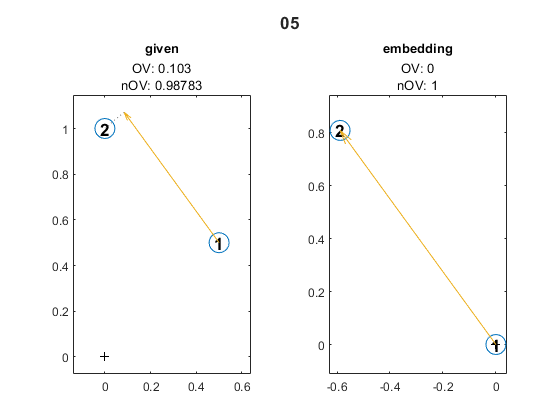

plotCompare("05",do);

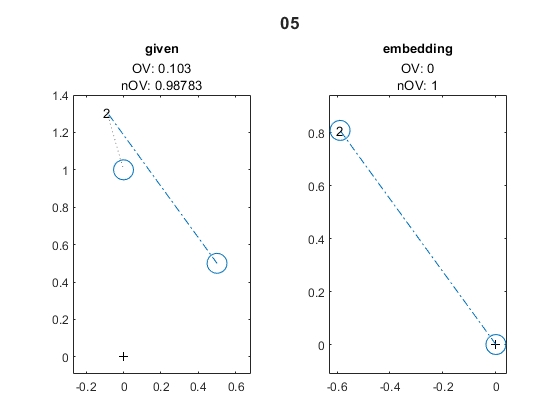

plotCompareOptions("05",1,1,0,0,1,1,1,1,do);

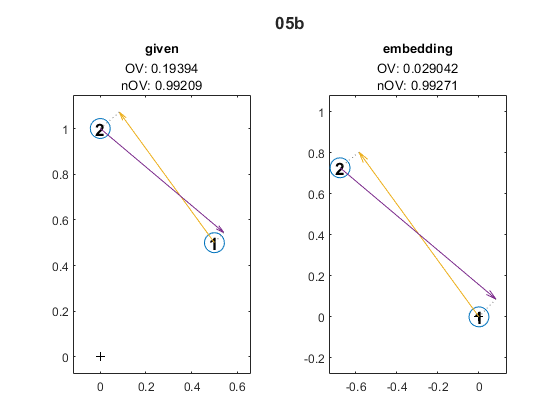

plotCompare("05b",do);

% plotCompareOptions("05b",1,1,0,1,1,0,1,1,do);

EDIT 20210207

this is no longer the case, this section will be remove shortly

This representational graph **06** does kinda do the desired job?! Adding edges does destroy this illusion though... Just lucky then?

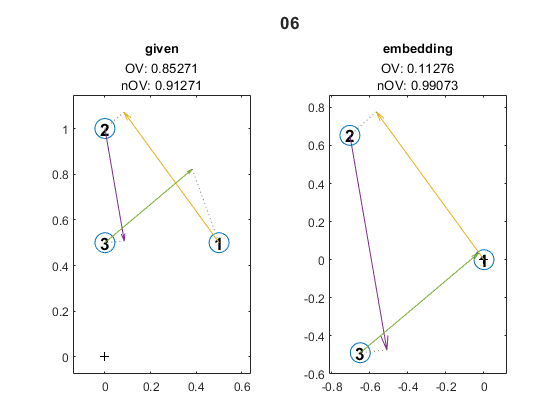

plotCompare("06",do);

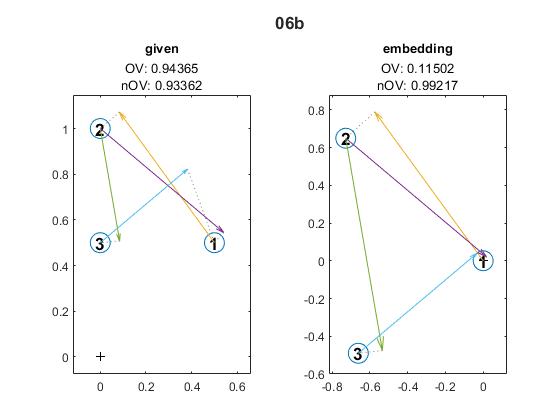

% load materials/06.mat emb
% emb1 = emb;
% plotCompareOptions("06",1,1,0,0,1,1,1,1,do);
plotCompare("06b",do);

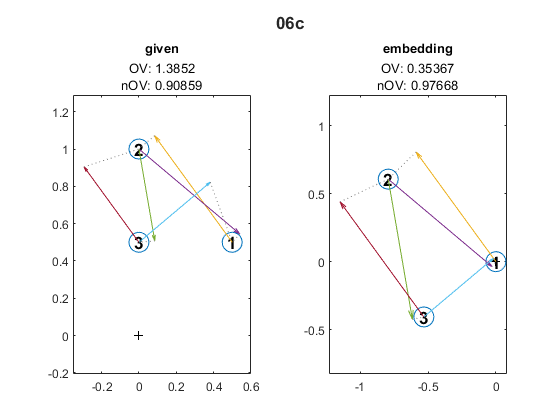

% load materials/06b.mat emb
% emb2 = emb;
% plotCompareOptions("06b",1,1,0,0,1,1,1,1,do);
plotCompare("06c",do);

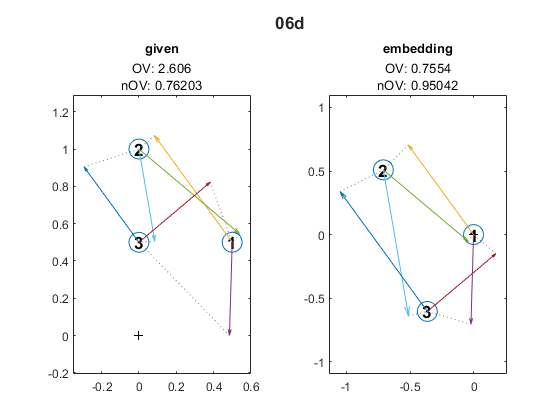

% load materials/06c.mat emb
% emb3 = emb;
% plotCompareOptions("06c",1,1,0,0,1,1,1,1,do);
plotCompare("06d",do);

% load materials/06d.mat emb
% emb4 = emb;
% plotCompareOptions("06d",1,1,0,0,1,1,1,1,do);
% clear emb

Interestingely enough, there is no difference in embeddings between every version of the **06 **graph. Currently every one got the embedding calculated as

% full(emb1)
% full(emb2)
% full(emb3)
% full(emb4)
% is currently
%          0         0
%    -0.9348    0.3412
%    -0.7648   -0.6442

This means, **adding** edges (with variing angles to be noted) does **not change **how the embeddings are calculated.

What **does change **the embeddings is the **angles **though (as seen from example graphs **04**)

Investigate this!!

It seems like the embedding does calculate the perfect embedding only for the edges (from-to-pairs) **2-3** and **3-1**... Same is done by **06** graphs apparently?!

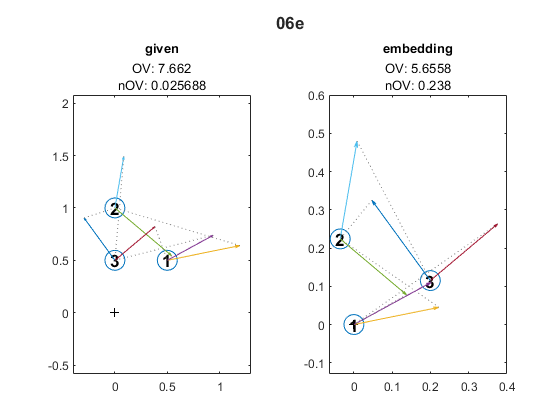

plotCompare("06e",do);

Minimum norm solution instead of the least square solution as our M is a 'fat' matrix, e.g. it has more columns than rows... (not needed anymore?)

[https://math.stackexchange.com/questions/381600/singular-matrix-problem](https://math.stackexchange.com/questions/381600/singular-matrix-problem)

***ITS IT DONE!!!!!!!***

THE LAST CHANGES DID IT, 04c FOR EXAMPLE IS PERFECT NOW!!!

plotCompare("small",0,[1,1]);
plotCompareOptions("small",0,1,0,0,0,1,0,1,0,[1,1]);


merging...
Elapsed time is 1.008220 seconds.

building M...
Elapsed time is 0.000281 seconds.

building P...
Elapsed time is 0.000169 seconds.


figure

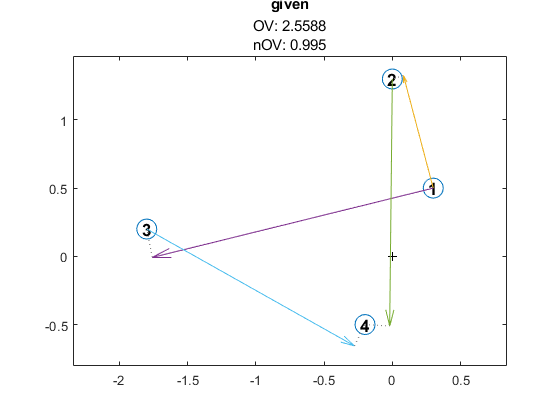


merging...
Elapsed time is 0.001184 seconds.

building M...
Elapsed time is 0.000072 seconds.

building P...
Elapsed time is 0.000066 seconds.


figure
plotData("visualization",0,1,0,1,1,1,0,1,0,1,0);

plotData("visualization",0,1,0,1,1,1,0,1,1,1,0);


merging...
Elapsed time is 0.001560 seconds.

building M...
Elapsed time is 0.000080 seconds.

building P...
Elapsed time is 0.000046 seconds.


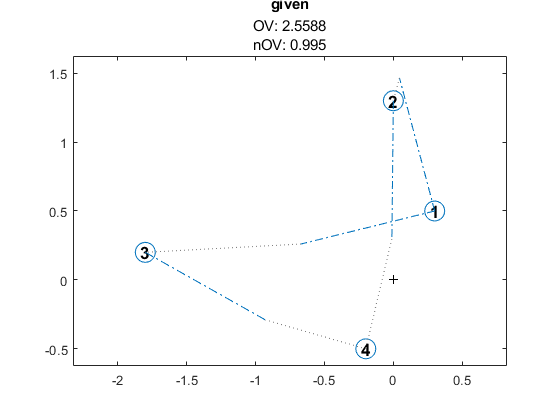


merging...
Elapsed time is 0.001738 seconds.

building M...
Elapsed time is 0.000097 seconds.

building P...
Elapsed time is 0.000067 seconds.


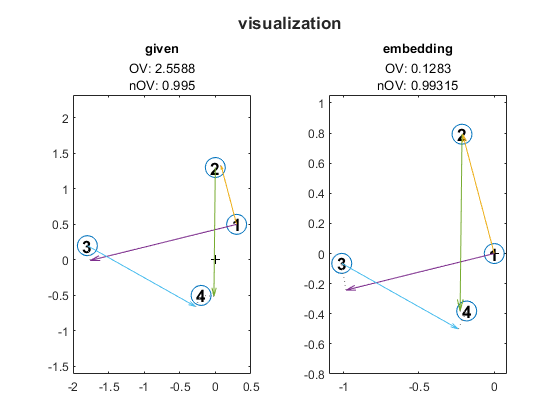

plotCompare("visualization",0,[1,1]);


merging...
Elapsed time is 0.000855 seconds.

building M...
Elapsed time is 0.000058 seconds.

building P...
Elapsed time is 0.000037 seconds.


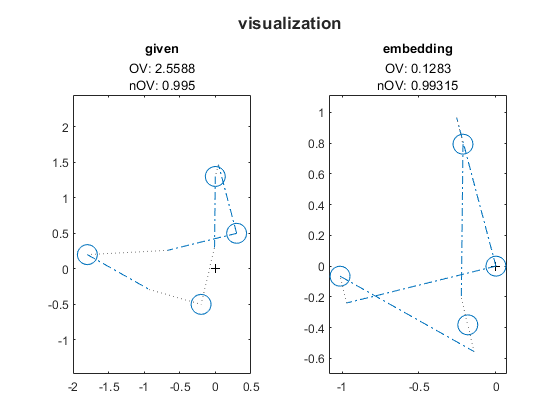

plotCompareOptions("visualization",0,1,1,0,0,1,1,1,0,[1,1]);